%To display an image...
clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
clear;  % Erase all existing variables. Or clearvars if you want.

idata = load('hw3_4.mat');
d = idata.d;
dc = idata.dc;
dpn = idata.dpn;
dcpn = idata.dcpn;
Rxx_est = idata.Rxx_est;
pattern = idata.pattern

pattern =    2.6452e-07   7.6013e-07   1.9546e-06   4.4974e-06   9.2602e-06   1.7062e-05    2.813e-05   4.1501e-05    5.479e-05   6.4727e-05   6.8424e-05   6.4727e-05    5.479e-05   4.1501e-05    2.813e-05   1.7062e-05   9.2602e-06   4.4974e-06   1.9546e-06   7.6013e-07   2.6452e-07
   7.6013e-07   2.1843e-06   5.6166e-06   1.2924e-05    2.661e-05   4.9028e-05   8.0834e-05   0.00011926   0.00015744     0.000186   0.00019662     0.000186   0.00015744   0.00011926   8.0834e-05   4.9028e-05    2.661e-05   1.2924e-05   5.6166e-06   2.1843e-06   7.6013e-07
   1.9546e-06   5.6166e-06   1.4442e-05   3.3232e-05   6.8424e-05   0.00012607   0.00020785   0.00030666   0.00040485   0.00047827   0.00050559   0.00047827   0.00040485   0.00030666   0.00020785   0.00012607   6.8424e-05   3.3232e-05   1.4442e-05   5.6166e-06   1.9546e-06
   4.4974e-06   1.2924e-05   3.3232e-05   7.6466e-05   0.00015744   0.00029008   0.00047827   0.00070561   0.00093154    0.0011005    0.0011634    0.0011005   0.0009315

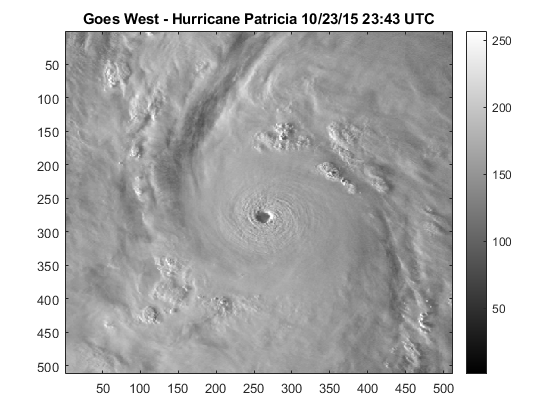

sigman = idata.sigman;
image(d);
colormap(repmat(linspace(0,1,256)',1,3));
colorbar
title('Goes West - Hurricane Patricia 10/23/15 23:43 UTC');

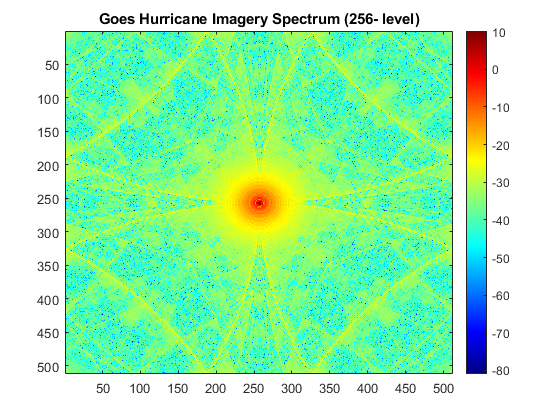

% To compute the process spectrum
Rxx = zeros(512,512);
ixm = 257; iym = 257;
for iix=1:512
    for iiy=1:512
        %what is this function doing?
        Rxx(iix,iiy)=Rxx_est(min([round(sqrt((iix-ixm)^2+(iiy-iym)^2)),255])+1);
    end
end
Rxx=Rxx*10*round(Rxx(257,257)/10)/Rxx(257,257);
Sxx=fftshift(abs(fft2(Rxx)));
Sxx=Rxx_est(1)*Sxx./sum(sum(Sxx)); %%process spectrum.
%To display a spectrum...
imagesc(10*log10(Sxx));
colormap('jet(256)');
title('Goes Hurricane Imagery Spectrum (256- level)');
colorbar




% noise spectra
Snn = 0.25*ones([512 512])/(512^2)*sigman^2; % normalized noise power spectra
Syy = Sxx + Snn;
Sxy = Sxx; %process spectrum

% forming the smoothing filter 
D = Sxy ./ Syy;

Yfft = fft2(dpn);
X = D.*Yfft; 


x = ifft2(X);

Sbb = Yfft;
var(d);
SNR_x = (d-x)./d;
mean_SNR_x = mean(mean(SNR_x))

mean_SNR_x =       0.18397

SNR_dpn = (d-dpn)./d;
mean_SNR_dpn = mean(mean(SNR_dpn))

mean_SNR_dpn =    1.9651e-05

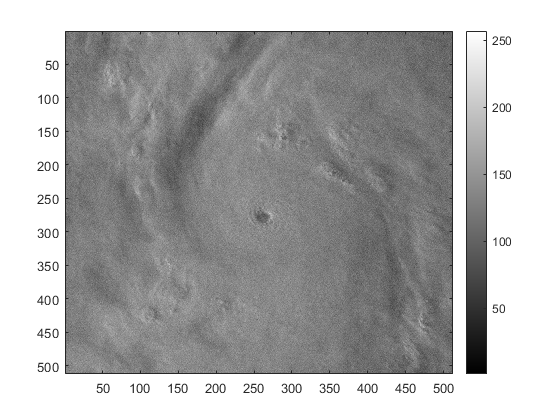


%image
image(x)
colormap(repmat(linspace(0,1,256)',1,3));colorbar

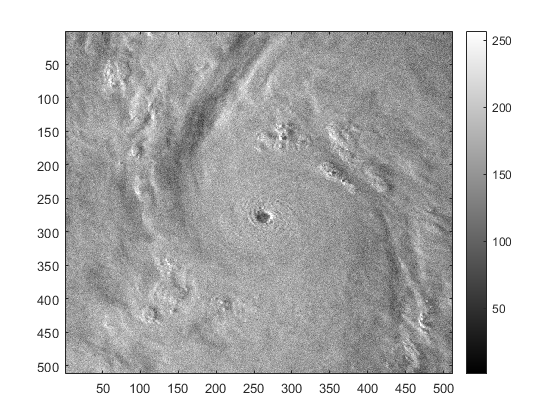

 image(dpn)
 colormap(repmat(linspace(0,1,256)',1,3));
 colorbar

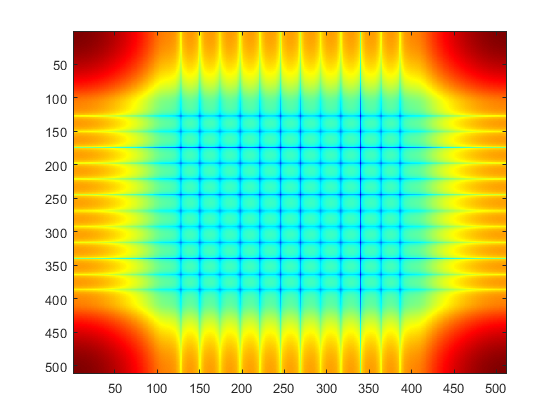


g = zeros(512,512);
g(246:266,246:266) = pattern;

G = fft2(g); 
% noise spectra
%image(g);
imagesc(10*log10(abs(G)));
colormap('jet(256)');

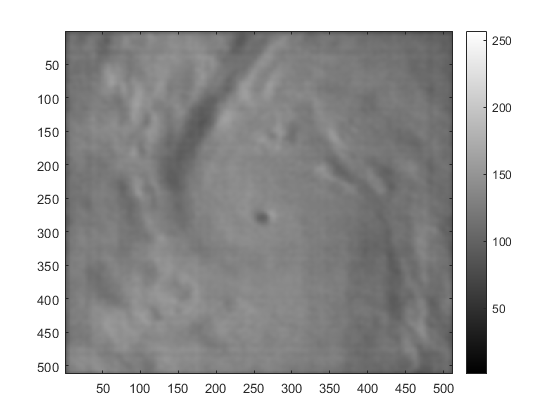

Sxy =conj(G).*Sxx;
Syy = G.*conj(G).*Sxx+Snn;
D = Sxy./Syy;
X = D.*fft2(dcpn)
x1 = ifftshift(ifft2(X));

image(x1)
colormap(repmat(linspace(0,1,256)',1,3));
colorbar

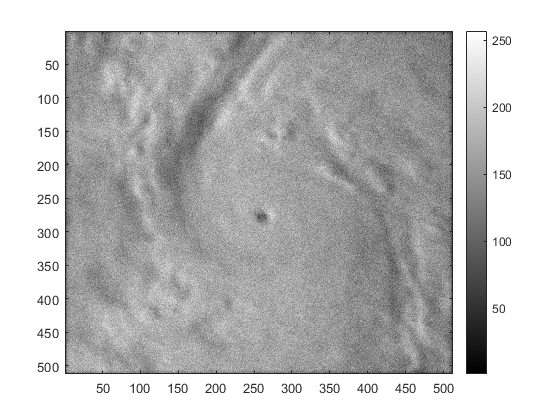

image(dcpn)
colormap(repmat(linspace(0,1,256)',1,3));
colorbar

SNR_x1 = (d-x1)./d;
mean_SNR_x1 = mean(mean(SNR_x1))

mean_SNR_x1 =        0.1901

SNR_dcpn = (d-dcpn)./d;
mean_SNR_dcpn = mean(mean(SNR_dcpn))

mean_SNR_dcpn =     0.0065766

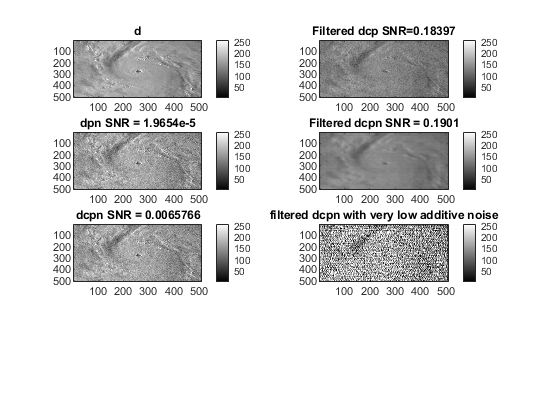


Snn = 0.0001*ones([512 512])/(512^2)*sigman^2; % normalized noise power spectra
Sxy =conj(G).*Sxx;
Syy = G.*conj(G).*Sxx+Snn;
D = Sxy./Syy;
X = D.*fft2(dcpn)
x2 = ifftshift(ifft2(X));

%image(x2)
%colormap(repmat(linspace(0,1,256)',1,3));
%colorbar


subplot(4,2,1)
image(d);
colormap(repmat(linspace(0,1,256)',1,3));
colorbar
title('d');

subplot(4,2,2)
image(x);
colormap(repmat(linspace(0,1,256)',1,3));
colorbar
title('Filtered dcp SNR=0.18397');

subplot(4,2,3)
image(dpn);
colormap(repmat(linspace(0,1,256)',1,3));
colorbar
title('dpn SNR = 1.9654e-5');
subplot(4,2,4)
image(x1);
colormap(repmat(linspace(0,1,256)',1,3));
colorbar
title('Filtered dcpn SNR = 0.1901');

subplot(4,2,5)
image(dpn );
colormap(repmat(linspace(0,1,256)',1,3));
colorbar
title('dcpn SNR = 0.0065766');

subplot(4,2,6)
image(x2);
colormap(repmat(linspace(0,1,256)',1,3));
colorbar
title('filtered dcpn with very low additive noise');